## Q2 - part c | ARMAX

clc; clear;

%%

load HW5_question2

u1 = Z1.u;
y1 = Z1.y;

u2 = Z2.u;
y2 = Z2.y;

u3 = Z3.u;
y3 = Z3.y;

u1_val = u1(601:end);
y1_val = y1(601:end);

u2_val = u2(601:end);
y2_val = y2(601:end);

u3_val = u1(601:end);
y3_val = y1(601:end);

u1 = u1(1:600);
y1 = y1(1:600);

u2 = u2(1:600);
y2 = y2(1:600);

u3 = u3(1:600);
y3 = y3(1:600);


### System I

%%

% System Z1 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System I Identification Begins:------------------------------\n")

>>> System I Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

data1 = iddata(y1,u1,Ts);



%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nk = 1;
    p = na+nb+nc;
    
    try
        sys = armax(data1, [na nb nc nk]);
        armax_y_hat_1 = lsim(sys, u1, t);
    catch
        break
    end

    [r2_armax, mse_armax] = rSQR(y1, armax_y_hat_1);

    error = y1 - armax_y_hat_1;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

%     theta = [sys.A sys.B sys.C];
%     covs = [covs; cov(theta)];
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_armax, mse_armax, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.080649 | MSE=76.927306 | var=77.313876 | s_hat=46156.383758 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.283547 | MSE=59.949681 | var=60.555233 | s_hat=35969.808577 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.920082 | MSE=6.687226 | var=6.789062 | s_hat=4012.335678 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.920432 | MSE=6.657940 | var=6.793816 | s_hat=3994.763805 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.920747 | MSE=6.631580 | var=6.801620 | s_hat=3978.947882 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.921126 | MSE=6.599870 | var=6.803990 | s_hat=3959.922044 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.922010 | MSE=6.525887 | var=6.762577 | s_hat=3915.531915 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.921277 | MSE=6.587202 | var=6.861669 | s_hat=3952.321167 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.922627 | MSE=6.474204 | var=6.779271 | s_hat=3884.522515 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.923640 | MSE=6.389483 | var=6.725772 | s_hat=3833.689899 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.922661 | MSE=6.471381 | var=6.848023 | s_hat=3882.828821 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.921376 | MSE=6.578956 | var=6.998889 | s_hat=3947.373605 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.922723 | MSE=6.466181 | var=6.915702 | s_hat=3879.708628 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.924222 | MSE=6.340771 | var=6.818033 | s_hat=3804.462682 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.925949 | MSE=6.196300 | var=6.698702 | s_hat=3717.779886 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.923542 | MSE=6.397703 | var=6.954025 | s_hat=3838.621805 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.925115 | MSE=6.266048 | var=6.848140 | s_hat=3759.628619 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.925110 | MSE=6.266484 | var=6.886247 | s_hat=3759.890603 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.924153 | MSE=6.346533 | var=7.012744 | s_hat=3807.919819 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.924061 | MSE=6.354210 | var=7.060233 | s_hat=3812.525879 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.927137 | MSE=6.096884 | var=6.812161 | s_hat=3658.130515 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.924725 | MSE=6.298685 | var=7.077174 | s_hat=3779.210880 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.925794 | MSE=6.209204 | var=7.016050 | s_hat=3725.522446 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.926549 | MSE=6.146046 | var=6.984143 | s_hat=3687.627719 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.926929 | MSE=6.114302 | var=6.987774 | s_hat=3668.581177 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.926950 | MSE=6.112539 | var=7.025907 | s_hat=3667.523245 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.925969 | MSE=6.194561 | var=7.161342 | s_hat=3716.736650 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.925885 | MSE=6.201612 | var=7.211177 | s_hat=3720.967253 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.925805 | MSE=6.208288 | var=7.261155 | s_hat=3724.972753 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=NaN | MSE=NaN | var=NaN | s_hat=NaN | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.925887 | MSE=6.201456 | var=7.339002 | s_hat=3720.873762 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.925871 | MSE=6.202758 | var=7.384236 | s_hat=3721.654884 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.926118 | MSE=6.182165 | var=7.403791 | s_hat=3709.299121 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.925499 | MSE=6.233889 | var=7.510709 | s_hat=3740.333185 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.924962 | MSE=6.278868 | var=7.610749 | s_hat=3767.320596 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.927080 | MSE=6.101667 | var=7.441057 | s_hat=3660.999989 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.927660 | MSE=6.053132 | var=7.427155 | s_hat=3631.878958 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.928244 | MSE=6.004211 | var=7.412606 | s_hat=3602.526624 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.924555 | MSE=6.312925 | var=7.842143 | s_hat=3787.754969 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.923598 | MSE=6.393008 | var=7.991260 | s_hat=3835.804858 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.926416 | MSE=6.157193 | var=7.744897 | s_hat=3694.315682 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.925513 | MSE=6.232763 | var=7.889573 | s_hat=3739.657720 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.924533 | MSE=6.314779 | var=8.044304 | s_hat=3788.867346 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.849272 | MSE=12.612235 | var=16.169532 | s_hat=7567.340771 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.927621 | MSE=6.056367 | var=7.814667 | s_hat=3633.820006 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.923527 | MSE=6.398909 | var=8.310272 | s_hat=3839.345476 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.928522 | MSE=5.980981 | var=7.818276 | s_hat=3588.588599 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=-27.283888 | MSE=2366.673784 | var=3114.044453 | s_hat=1420004.270589 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.926954 | MSE=6.112141 | var=8.095551 | s_hat=3667.284457 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.914470 | MSE=7.156823 | var=9.542431 | s_hat=4294.094091 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.928935 | MSE=5.946416 | var=7.981766 | s_hat=3567.849364 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.916994 | MSE=6.945614 | var=9.385965 | s_hat=4167.368571 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=-234772.835614 | MSE=19644862.518363 | var=26727704.106616 | s_hat=11786917511.017809 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.925944 | MSE=6.196665 | var=8.488583 | s_hat=3717.999187 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.928178 | MSE=6.009741 | var=8.289297 | s_hat=3605.844301 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.926862 | MSE=6.119893 | var=8.499852 | s_hat=3671.936056 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.926755 | MSE=6.128811 | var=8.571764 | s_hat=3677.286871 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.927379 | MSE=6.076618 | var=8.558617 | s_hat=3645.970749 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=-2238.386061 | MSE=187382.172233 | var=265790.315225 | s_hat=112429303.340044 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.922385 | MSE=6.494488 | var=9.277840 | s_hat=3896.692693 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.928318 | MSE=5.998063 | var=8.630306 | s_hat=3598.837766 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.923548 | MSE=6.397215 | var=9.271326 | s_hat=3838.328803 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.924783 | MSE=6.293832 | var=9.188076 | s_hat=3776.299325 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.921746 | MSE=6.547962 | var=9.629356 | s_hat=3928.777198 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.924458 | MSE=6.321023 | var=9.364478 | s_hat=3792.613731 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.923136 | MSE=6.431689 | var=9.599536 | s_hat=3859.013517 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.925707 | MSE=6.216527 | var=9.348161 | s_hat=3729.916368 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.911162 | MSE=7.433542 | var=11.262943 | s_hat=4460.125316 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=-0.983424 | MSE=165.964334 | var=253.380663 | s_hat=99578.600385 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.776832 | MSE=18.673715 | var=28.728792 | s_hat=11204.228818 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.892530 | MSE=8.992666 | var=13.942119 | s_hat=5395.599898 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.927069 | MSE=6.102585 | var=9.535289 | s_hat=3661.550898 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 51 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc;

BestFitModel_1 = armax(data1, [na nb nc 1])

BestFitModel_1 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                                
                                                                                                         
  A(z) = 1 + 0.2833 z^-1 + 0.02414 z^-2 - 0.06437 z^-3 - 0.329 z^-4 + 0.07484 z^-5 - 0.2868 z^-6         
          + 0.2099 z^-7 + 0.1113 z^-8 + 0.1013 z^-9 - 0.2052 z^-10 - 0.02271 z^-11 + 0.07545 z^-12       
          - 0.08059 z^-13 + 0.0368 z^-14 - 0.2083 z^-15 + 0.008896 z^-16 - 0.06353 z^-17 - 0.3018 z^-18  
          + 0.029 z^-19 + 0.1839 z^-20 + 0.03226 z^-21 + 0.05514 z^-22 - 0.08423 z^-23 + 0.02432 z^-24   
          + 0.09121 z^-25 - 0.06995 z^-26 + 0.1317 z^-27 - 0.03288 z^-28 - 0.07743 z^-29 - 0.1287 z^-30  
          + 0.02587 z^-31 + 0.1666 z^-32 + 0.04988 z^-33 + 0.05126 z^-34 - 0.05232 z^-35 + 0.03721 z^-36 
          + 0.1048 z^-37 + 0.08769 z^-38 + 0.06335 z^-39 - 0.1915 z^-40 - 0.09423 z^-41 + 0.009659 z^-42 
          - 0.04501 z^-43 + 0

BestFit_y_hat_1 = lsim(BestFitModel_1, u1_val, t_val);
% [armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 15 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 15 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc;

armax_VarModel_1 = armax(data1, [na nb nc nk]);
Var_y_hat_1 = lsim(armax_VarModel_1, u1_val, t_val);
% [armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%
% 
% fprintf("===============Degree Extraction | CoVariance Method=================\n")
% 
% maxCovIndex = find(covs == max(covs),1);
% fprintf(">>> Since the maximum accuracy occurs in iteration %d ;\n", maxCovIndex)
% fprintf("    Degree = %d \n", maxCovIndex)
% na = maxCovIndex;
% nb = maxCovIndex;
% nc = maxCovIndex;
% p = na+nb+nc+1;
% 
% armax_CovModel_1 = armax(data1, [na nb nc 1]);
% Cov_y_hat_1 = lsim(armax_CovModel_1, u1_val, t_val);
% 
% fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 3 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 3 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc;

armax_AICModel_1 = armax(data1, [na nb nc nk])

armax_AICModel_1 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.637 z^-1 + 2.528 z^-2 - 0.8876 z^-3       
                                                         
  B(z) = 0.6649 z^-1 + 0.1202 z^-2 - 0.4849 z^-3         
                                                         
  C(z) = 1 - 2.658 z^-1 + 2.567 z^-2 - 0.9095 z^-3       
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data1".
Fit to estimation data: 71.8% (prediction focus)  
FPE: 6.856, MSE: 6.653                            


AIC_y_hat_1 = lsim(armax_AICModel_1, u1_val, t_val);
% [armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.20 as


fprintf("    Degree = %d \n", winner)

    Degree = 3 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc;

armax_FTestModel_1 = armax(data1, [na nb nc nk])

armax_FTestModel_1 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.637 z^-1 + 2.528 z^-2 - 0.8876 z^-3       
                                                         
  B(z) = 0.6649 z^-1 + 0.1202 z^-2 - 0.4849 z^-3         
                                                         
  C(z) = 1 - 2.658 z^-1 + 2.567 z^-2 - 0.9095 z^-3       
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data1".
Fit to estimation data: 71.8% (prediction focus)  
FPE: 6.856, MSE: 6.653                            


FTest_y_hat_1 = lsim(armax_FTestModel_1, u1_val, t_val);
% [armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")


%%

[armax_BestFit_r2_1, armax_BestFit_mse_1] = rSQR(y1_val, BestFit_y_hat_1);
[armax_Var_r2_1, armax_Var_mse_1] = rSQR(y1_val, Var_y_hat_1);
[armax_AIC_r2_1, armax_AIC_mse_1] = rSQR(y1_val, AIC_y_hat_1);
[armax_FTest_r2_1, armax_FTest_mse_1] = rSQR(y1_val, FTest_y_hat_1);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_BestFit_r2_1, armax_BestFit_mse_1)

    R2 value : 0.6559   | MSE : 25.4468 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Var_r2_1, armax_Var_mse_1)

    R2 value : 0.6574   | MSE : 25.3383 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Cov_r2, armax_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_AIC_r2_1, armax_AIC_mse_1)

    R2 value : 0.6627   | MSE : 24.9455 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_FTest_r2_1, armax_FTest_mse_1)

    R2 value : 0.6627   | MSE : 24.9455 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")



%%

armax_BestFitError_1 = y1_val - BestFit_y_hat_1;
armax_VarError_1 = y1_val - Var_y_hat_1;
armax_AICError_1 = y1_val - AIC_y_hat_1;
armax_FTestError_1 = y1_val - FTest_y_hat_1;

for k=0:N_val-1
    armax_BestFit_Ree_1(k+1,1) = AutoCorrelate(armax_BestFitError_1, k);
    armax_Var_Ree_1(k+1,1) = AutoCorrelate(armax_VarError_1, k);
    armax_AIC_Ree_1(k+1,1) = AutoCorrelate(armax_AICError_1, k);
    armax_FTest_Ree_1(k+1,1) = AutoCorrelate(armax_FTestError_1, k);
end

for k=0:N_val-1
    armax_BestFit_Rue_1(k+1,1) = CrossCorrelate(u1_val, armax_BestFitError_1, k);
    armax_Var_Rue_1(k+1,1) = CrossCorrelate(u1_val, armax_VarError_1, k);
    armax_AIC_Rue_1(k+1,1) = CrossCorrelate(u1_val, armax_AICError_1, k);
    armax_FTest_Rue_1(k+1,1) = CrossCorrelate(u1_val, armax_FTestError_1, k);
end


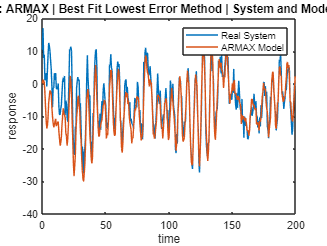


%%
figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_1)
legend('Real System','ARMAX Model')
title(" System I : ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

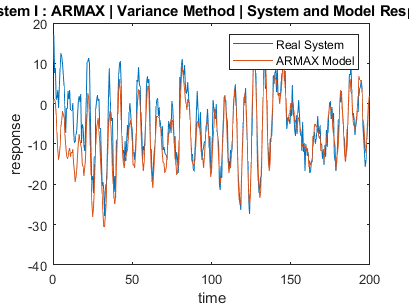


figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_1)
legend('Real System','ARMAX Model')
title(" System I : ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

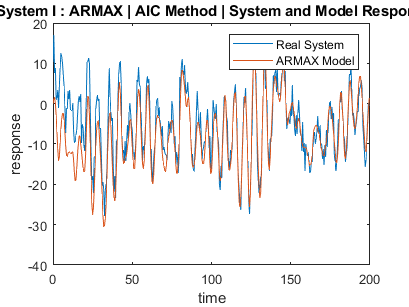


figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_1)
legend('Real System','ARMAX Model')
title(" System I : ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

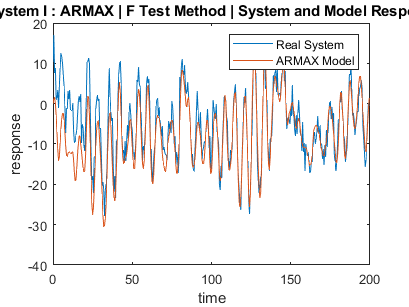


figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_1)
legend('Real System','ARMAX Model')
title(" System I : ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

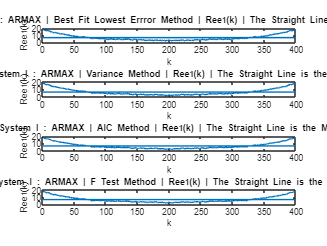


%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Ree_1(2:end), 1:N_val-1, mean(armax_BestFit_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | Best Fit Lowest Errror Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Ree_1(2:end), 1:N_val-1, mean(armax_Var_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | Variance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Ree_1(2:end), 1:N_val-1, mean(armax_AIC_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | AIC Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Ree_1(2:end), 1:N_val-1, mean(armax_FTest_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | F Test Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

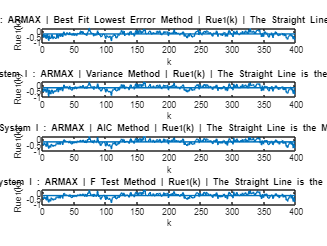


%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Rue_1(2:end), 1:N_val-1, mean(armax_BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Rue_1(2:end), 1:N_val-1, mean(armax_Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Rue_1(2:end), 1:N_val-1, mean(armax_AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Rue_1(2:end), 1:N_val-1, mean(armax_FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARMAX | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

### System II

%%

% System Z2 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System II Identification Begins:------------------------------\n")

>>> System II Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

data2 = iddata(y2,u2,Ts);



%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nk = 1;
    p = na+nb+nc;
    
    try
        sys = armax(data2, [na nb nc nk]);
        armax_y_hat_2 = lsim(sys, u2, t);
    catch
        break
    end

    [r2_armax, mse_armax] = rSQR(y2, armax_y_hat_2);

    error = y2 - armax_y_hat_2;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_armax, mse_armax, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.076105 | MSE=69.293914 | var=69.642125 | s_hat=41576.348374 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.670105 | MSE=24.742754 | var=24.992681 | s_hat=14845.652283 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.669880 | MSE=24.759631 | var=25.136681 | s_hat=14855.778603 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=-30.247620 | MSE=2343.631100 | var=2391.460306 | s_hat=1406178.659745 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=-40238886695571098383155200.000000 | MSE=3017993230006034208540065792.000000 | var=3095377671801060543455821824.000000 | s_hat=1810795938003620388784597630976.000000 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=-24225.169220 | MSE=1817008.886138 | var=1873205.037256 | s_hat=1090205331.683068 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=-739086.490314 | MSE=55432971.071652 | var=57443493.338499 | s_hat=33259782642.991188 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=-69809.682214 | MSE=5235934.281636 | var=5454098.210037 | s_hat=3141560568.981592 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=-256.249162 | MSE=19294.177681 | var=20203.327414 | s_hat=11576506.608390 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=-166733.899968 | MSE=12505435.429084 | var=13163616.241141 | s_hat=7503261257.450581 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=-66230.650401 | MSE=4967500.071155 | var=5256613.831911 | s_hat=2980500042.693299 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=-7774946496.723517 | MSE=583135812660.824707 | var=620357247511.514526 | s_hat=349881487596494.187500 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=-12583011.268630 | MSE=943749913.537949 | var=1009358196.297272 | s_hat=566249948122.769409 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=-996418.652626 | MSE=74733373.928118 | var=80358466.589374 | s_hat=44840024356.870613 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=-3335875.305350 | MSE=250197083.777431 | var=270483333.813439 | s_hat=150118250266.458801 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=-58275248.362466 | MSE=4370754821.906986 | var=4750820458.594545 | s_hat=2622452893144.188965 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=-1695447573.266020 | MSE=127161800963.250519 | var=138974645861.476440 | s_hat=76297080577950.562500 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=-30110056688.674244 | MSE=2258311665827.886719 | var=2481661171239.435547 | s_hat=1354986999496731.750000 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=-6086304.781440 | MSE=456484539.025645 | var=504402805.553198 | s_hat=273890723415.386719 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=-1111868769.854708 | MSE=83392277934.567581 | var=92658086593.964066 | s_hat=50035366760740.593750 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=-73664.534067 | MSE=5525055.521062 | var=6173246.392248 | s_hat=3315033312.637136 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=-72382735120842832.000000 | MSE=5428843154054445056.000000 | var=6099823768600512512.000000 | s_hat=3257305892432673505280.000000 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.607638 | MSE=29.427870 | var=33.251830 | s_hat=17656.721960 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.609993 | MSE=29.251246 | var=33.240053 | s_hat=17550.747781 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.336169 | MSE=49.788613 | var=56.901272 | s_hat=29873.167575 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.520487 | MSE=35.964394 | var=41.338383 | s_hat=21578.636110 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.666492 | MSE=25.013737 | var=28.917615 | s_hat=15008.242382 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=-2.790878 | MSE=284.323077 | var=330.608229 | s_hat=170593.846241 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.359757 | MSE=48.019470 | var=56.163123 | s_hat=28811.682216 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=-652034.423248 | MSE=48903900.050079 | var=57534000.058917 | s_hat=29342340030.047668 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=-1250066.156720 | MSE=93757420.392267 | var=110955527.091440 | s_hat=56254452235.360199 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.673498 | MSE=24.488294 | var=29.152731 | s_hat=14692.976349 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=-204379467.875462 | MSE=15328849878.102179 | var=18357904045.631359 | s_hat=9197309926861.310547 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=-542674.516853 | MSE=40701698.542077 | var=49038191.014551 | s_hat=24421019125.246372 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=-938440967.417897 | MSE=70384862058.254852 | var=85314984313.036194 | s_hat=42230917234952.914062 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=-537856234.310637 | MSE=40340243236.965546 | var=49195418581.665367 | s_hat=24204145942179.359375 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=-1119561.407924 | MSE=83969315.385071 | var=103029834.828308 | s_hat=50381589231.042549 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=-1691968658238720164220146548736.000000 | MSE=126900875627577497992812382126080.000000 | var=156667747688367245443810860204032.000000 | s_hat=76140525376546485392974938221051904.000000 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=-19247650813552774946488320.000000 | MSE=1443610512594425407504121856.000000 | var=1793304984589348847912747008.000000 | s_hat=866166307556655446812612624384.000000 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=-603.648722 | MSE=45349.807062 | var=56687.258828 | s_hat=27209884.237478 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=-4029679962825685080018518016.000000 | MSE=302233681038631895752226373632.000000 | var=380168152249851469964865699840.000000 | s_hat=181340208623179141110510521417728.000000 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=-49750392009159200974679375335224452566656391485634282609960701509519215819692368199680.000000 | MSE=3731374265141253136974569187563242039405543891645341555769721405360196647560196741136384.000000 | var=4723258563469940109403250214019288602107191395191291164254845192502990286772930900656128.000000 | s_hat=2238824559084751793842388273618728744478451297841279142087637999435170082455807980050841600.000000 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=-11154311.703088 | MSE=836594721.866295 | var=1065725760.339230 | s_hat=501956833119.777222 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=-815165.123898 | MSE=61139013.657762 | var=78383350.843284 | s_hat=36683408194.656975 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=-1119380.012590 | MSE=83955710.389085 | var=108329948.889142 | s_hat=50373426233.451019 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=-254477.184236 | MSE=19086349.058812 | var=24787466.310146 | s_hat=11451809435.287413 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=-144994195.953928 | MSE=10874841247.664993 | var=14215478755.117641 | s_hat=6524904748598.997070 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=-1903934744.459510 | MSE=142798736347.805145 | var=187893074141.848785 | s_hat=85679241808683.046875 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=-1153309387.328254 | MSE=86500403264.391846 | var=114570070548.863342 | s_hat=51900241958635.093750 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=-114016272.406835 | MSE=8551437912.675125 | var=11401917216.900164 | s_hat=5130862747605.073242 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=-85531811.481076 | MSE=6415049028.840205 | var=8610804065.557327 | s_hat=3849029417304.125000 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=-44899280.119394 | MSE=3367531698.270926 | var=4550718511.176935 | s_hat=2020519018962.559326 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=-45575221.605664 | MSE=3418228598.631987 | var=4650651154.601343 | s_hat=2050937159179.192383 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=-89739659.638364 | MSE=6730645664.196054 | var=9220062553.693235 | s_hat=4038387398517.637207 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=-23936003.063205 | MSE=1795245946.108655 | var=2476201304.977458 | s_hat=1077147567665.194458 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=-694713185.150772 | MSE=52104813646.092186 | var=72367796730.683533 | s_hat=31262888187655.289062 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=-128324089.066744 | MSE=9624551444.430111 | var=13460911111.091053 | s_hat=5774730866658.061523 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=-7095215745.156698 | MSE=532154710177.157715 | var=749513676305.855957 | s_hat=319292826106294.625000 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=-63327901.317026 | MSE=4749713427.938927 | var=6737182167.289258 | s_hat=2849828056763.355957 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=-251427185203.018890 | MSE=18857518313714.191406 | var=26939311876734.558594 | s_hat=11314510988228514.000000 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=-87191673229951991461129421517292134304815102558208.000000 | MSE=6539541750041916629459360820665882931410495961300992.000000 | var=9409412589988370962760312299518833352975273254977536.000000 | s_hat=3923725050025150955987421390097612216048293943114203136.000000 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=-625174278.917282 | MSE=46889263081.225380 | var=67955453740.906319 | s_hat=28133557848735.214844 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=-2801756.222029 | MSE=210137134.065747 | var=306769538.782113 | s_hat=126082280439.448288 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=-7366754.262731 | MSE=552520691.694018 | var=812530428.961792 | s_hat=331512415016.411133 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=-36219187.170655 | MSE=2716508175.843311 | var=4024456556.804911 | s_hat=1629904905505.988770 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=-6616499.359666 | MSE=496250143.371941 | var=740671855.779017 | s_hat=297750086023.164734 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=-3035060.495868 | MSE=227635399.470209 | var=342308871.383772 | s_hat=136581239682.125122 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=-11950124791867392.000000 | MSE=896282145985728896.000000 | var=1358003251493528832.000000 | s_hat=537769287591437402112.000000 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=-104996697673.003769 | MSE=7874952534112.009766 | var=12022828296354.212891 | s_hat=4724971520467206.000000 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=-8547258.687897 | MSE=641060774.576959 | var=986247345.503014 | s_hat=384636464746.175598 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=-1213561024237.416504 | MSE=91019390845966.046875 | var=141115334644908.625000 | s_hat=54611634507579640.000000 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=-103138073.433910 | MSE=7735552247.066959 | var=12086800386.042124 | s_hat=4641331348240.175781 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=-27359.254468 | MSE=2052071.255887 | var=3231608.276988 | s_hat=1231242753.532333 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=-909778170.741116 | MSE=68235097653.041222 | var=108309678814.351105 | s_hat=40941058591824.718750 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 32 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc;

BestFitModel_2 = armax(data2, [na nb nc 1])

BestFitModel_2 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                                 
                                                                                                          
  A(z) = 1 - 0.1298 z^-1 - 0.5515 z^-2 + 0.5311 z^-3 + 0.2281 z^-4 - 0.8008 z^-5 + 0.1028 z^-6            
          + 0.4015 z^-7 - 0.473 z^-8 - 0.3776 z^-9 + 0.4806 z^-10 - 0.07343 z^-11 - 0.2202 z^             
          -12 + 0.375 z^-13 - 0.07283 z^-14 - 0.08965 z^-15 + 0.2112 z^-16 - 0.02517 z^-17 - 0.2289 z^-18 
          + 0.1477 z^-19 - 0.05333 z^-20 + 0.003588 z^-21 + 0.2317 z^-22 - 0.2229 z^-23 - 0.288 z^-24     
          + 0.2889 z^-25 - 0.0665 z^-26 - 0.2729 z^-27 + 0.281 z^-28 + 0.07074 z^-29 - 0.1327 z^-30       
                                                                        - 0.09726 z^-31 + 0.148 z^-32     
                                                                                                          
                    

BestFit_y_hat_2 = lsim(BestFitModel_2, u2_val, t_val);
% [armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 2 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 2 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc;

armax_VarModel_2 = armax(data2, [na nb nc nk])

armax_VarModel_2 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.638 z^-1 + 0.884 z^-2                     
                                                         
  B(z) = -0.4923 z^-1 + 1.759 z^-2                       
                                                         
  C(z) = 1 - 1.683 z^-1 + 0.9285 z^-2                    
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data2".
Fit to estimation data: 42.73% (prediction focus) 
FPE: 25.1, MSE: 24.6                              


Var_y_hat_2 = lsim(armax_VarModel_2, u2_val, t_val);
% [armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc;

armax_AICModel_2 = armax(data2, [na nb nc nk])

armax_AICModel_2 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.638 z^-1 + 0.884 z^-2                     
                                                         
  B(z) = -0.4923 z^-1 + 1.759 z^-2                       
                                                         
  C(z) = 1 - 1.683 z^-1 + 0.9285 z^-2                    
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data2".
Fit to estimation data: 42.73% (prediction focus) 
FPE: 25.1, MSE: 24.6                              


AIC_y_hat_2 = lsim(armax_AICModel_2, u2_val, t_val);
% [armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.20 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc;

armax_FTestModel_2 = armax(data2, [na nb nc nk])

armax_FTestModel_2 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.638 z^-1 + 0.884 z^-2                     
                                                         
  B(z) = -0.4923 z^-1 + 1.759 z^-2                       
                                                         
  C(z) = 1 - 1.683 z^-1 + 0.9285 z^-2                    
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data2".
Fit to estimation data: 42.73% (prediction focus) 
FPE: 25.1, MSE: 24.6                              


FTest_y_hat_2 = lsim(armax_FTestModel_2, u2_val, t_val);
% [armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")


%%

[armax_BestFit_r2_2, armax_BestFit_mse_2] = rSQR(y2_val, BestFit_y_hat_2);
[armax_Var_r2_2, armax_Var_mse_2] = rSQR(y2_val, Var_y_hat_2);
[armax_AIC_r2_2, armax_AIC_mse_2] = rSQR(y2_val, AIC_y_hat_2);
[armax_FTest_r2_2, armax_FTest_mse_2] = rSQR(y2_val, FTest_y_hat_2);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_BestFit_r2_2, armax_BestFit_mse_2)

    R2 value : 0.6946   | MSE : 26.9895 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Var_r2_2, armax_Var_mse_2)

    R2 value : 0.7020   | MSE : 26.3329 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Cov_r2, armax_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_AIC_r2_2, armax_AIC_mse_2)

    R2 value : 0.7020   | MSE : 26.3329 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_FTest_r2_2, armax_FTest_mse_2)

    R2 value : 0.7020   | MSE : 26.3329 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

armax_BestFitError_2 = y2_val - BestFit_y_hat_2;
armax_VarError_2 = y2_val - Var_y_hat_2;
armax_AICError_2 = y2_val - AIC_y_hat_2;
armax_FTestError_2 = y2_val - FTest_y_hat_2;

for k=0:N_val-1
    armax_BestFit_Ree_2(k+1,1) = AutoCorrelate(armax_BestFitError_2, k);
    armax_Var_Ree_2(k+1,1) = AutoCorrelate(armax_VarError_2, k);
    armax_AIC_Ree_2(k+1,1) = AutoCorrelate(armax_AICError_2, k);
    armax_FTest_Ree_2(k+1,1) = AutoCorrelate(armax_FTestError_2, k);
end

for k=0:N_val-1
    armax_BestFit_Rue_2(k+1,1) = CrossCorrelate(u2_val, armax_BestFitError_2, k);
    armax_Var_Rue_2(k+1,1) = CrossCorrelate(u2_val, armax_VarError_2, k);
    armax_AIC_Rue_2(k+1,1) = CrossCorrelate(u2_val, armax_AICError_2, k);
    armax_FTest_Rue_2(k+1,1) = CrossCorrelate(u2_val, armax_FTestError_2, k);
end


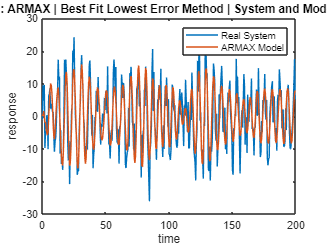


%%
figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_2)
legend('Real System','ARMAX Model')
title(" System II : ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

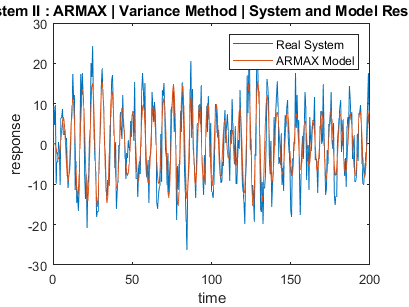


figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_2)
legend('Real System','ARMAX Model')
title(" System II : ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

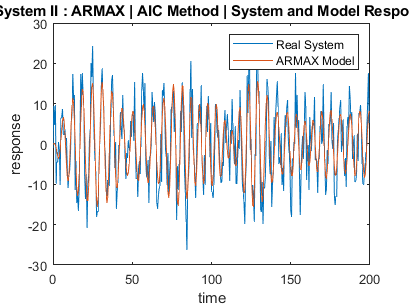


figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_2)
legend('Real System','ARMAX Model')
title(" System II : ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

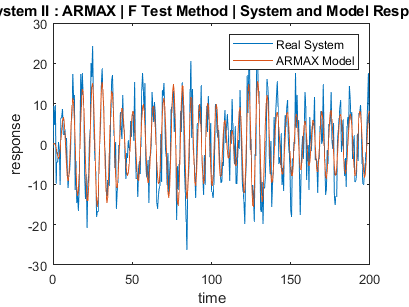


figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_2)
legend('Real System','ARMAX Model')
title(" System II : ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

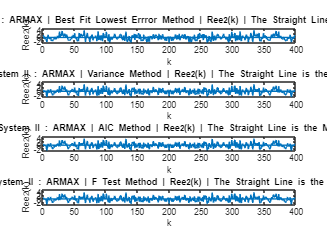


%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Ree_2(2:end), 1:N_val-1, mean(armax_BestFit_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | Best Fit Lowest Errror Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Ree_2(2:end), 1:N_val-1, mean(armax_Var_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | Variance Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Ree_2(2:end), 1:N_val-1, mean(armax_AIC_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | AIC Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Ree_2(2:end), 1:N_val-1, mean(armax_FTest_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | F Test Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

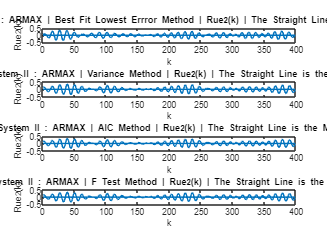


%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Rue_2(2:end), 1:N_val-1, mean(armax_BestFit_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | Best Fit Lowest Errror Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Rue_2(2:end), 1:N_val-1, mean(armax_Var_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | Variance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Rue_2(2:end), 1:N_val-1, mean(armax_AIC_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | AIC Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Rue_2(2:end), 1:N_val-1, mean(armax_FTest_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : ARMAX | F Test Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")